# Lab 3.  Bifurcaciones Saddle-Node, Transcritical, Supercritical Pitchfork & Subcritical Pitchfork (Tridente).

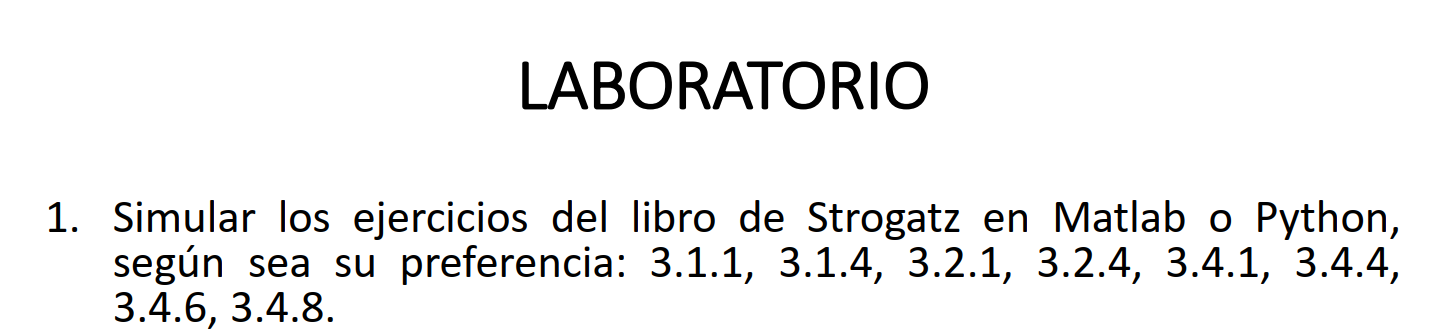

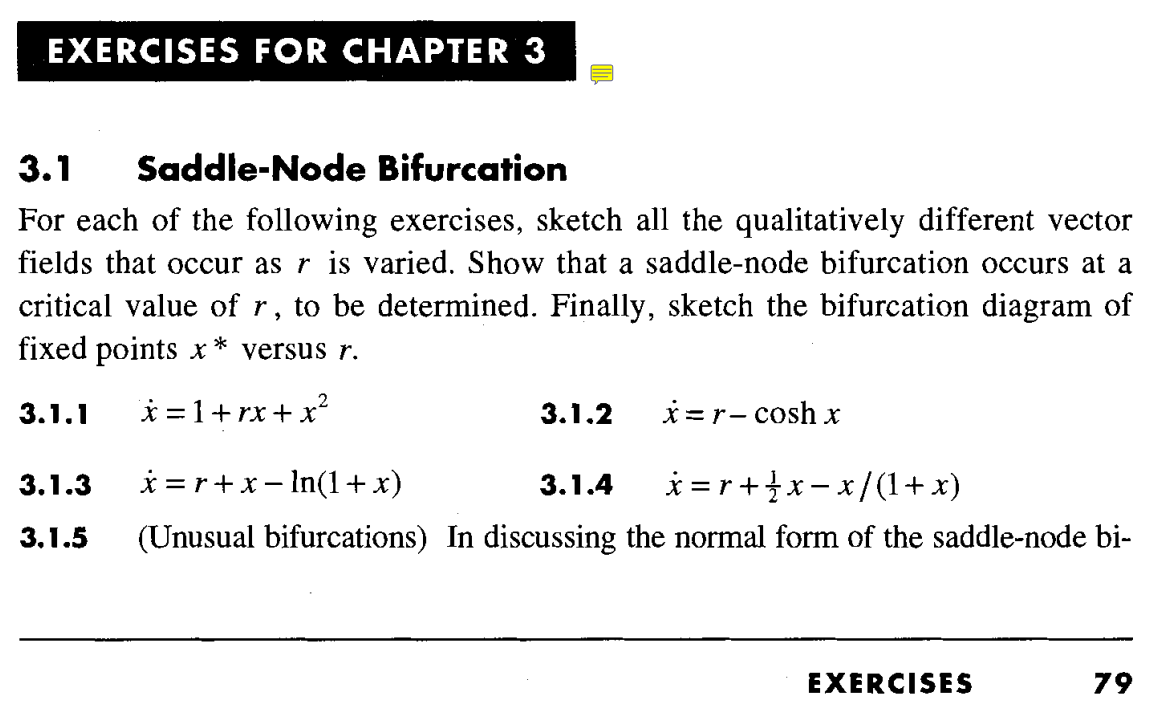

# 3.1.4  Saddle Node Bifurcation.

# Bifurcaciones en sistemas unidimensionales

clc;clear;close all

Para este tipo de bifurcación, se analiza el siguiente sistema:


$$\dot{x} =r+\frac{1}{2}x-\frac{x}{\left(1+x\right)}\ldotp$$


Donde $r$ es el parámetro de bifurcación

syms x r
Fsn = r+1/2*x-x/(1+x)


% GRAFICA X*(x) con variantes de r:
r_desde=-5; r_hasta=5; r_paso=5;
r_grafica=r_desde:r_paso:r_hasta; %Asigno valor.
x_desde=-10; x_hasta=10;
x_grafica=linspace(x_desde,x_hasta,100);
for i = 1:length(r_grafica)
    Fsn_grafica=real(subs(subs(Fsn,r,r_grafica(i)),x,x_grafica)); %sustituye r y x por valor numéricos.
    plot(x_grafica,Fsn_grafica); %Grafica Fsn con variantes de r.
    hold on;
end
%ylim([-15 15])
grid on
title("X*(x)");
xlabel("x");
ylabel("X*");
% Crear leyenda para indicar valores de r
legendStrings = cellstr(num2str(r_grafica', 'r=%g'));
legend(legendStrings, 'Location', 'best');
hold off;

Para analizar este sistema, se encuentra los PE, linealizando alrededor de estos puntos y se analiza la estabilidad de cada uno.

xss_sn = simplify(solve(Fsn==0,x),"Steps",100) %resuelve eca, despeja X y simplifica hasta 100 pásos.

En este caso, tenemos 2 PE. Por lo que se linealiza en estos puntos

A = jacobian(Fsn,x); %Linealiza.

A_a = subs(A,x,xss_sn(1)) % Para el punto de equilibrio 1
A_b = subs(A,x,xss_sn(2)) % Para PE 2, collect agrupa fracción.
%Intento de resolver valores de r que hagan cero el denominador.
syms r_x
denominador_A_a=((sqrt(4*r_x^2-12*r_x+1)/2)-r_x+3/2)^2
denominador_A_b=(sqrt(4*r_x^2-12*r_x+1)/2-r_x+3/2)
denominador_A_a_op2=solve((4*r_x^2-12*r_x+1)<0,r_x)
denominador_A_b_op2=solve((4*r_x^2-12*r_x+1)<0,r_x)
assume(r>denominador_A_a_op2)
denomindador_A_a_op3=solve(denominador_A_a==0)
denominador_A_b_op3=denominador_A_b_op2/2-denominador_A_b_op2+3/2
r_indeterminador_A_a=solve(denominador_A_a,r_x,"Real",true,"PrincipalValue",true)
r_indeterminador_A_b=solve(denominador_A_b,r_x,"Real",true,"PrincipalValue",true)
%Asigna valor para resolver para ese punto (mas factible) quiero resultado REAL:
r_asignado=5 %Asignamos valor para probar.


A_a_posible=double(subs(A_a,r,r_asignado)) %Sustituye r por valor.
A_b_posible=double(subs(A_b,r,r_asignado))

En este caso, para los dos PE se hace el siguiente análisis:

xss_sn_num = double(subs(xss_sn,r,r_asignado))
disp("Los valores xss_sn_num es a donde tienden o se aleja en gráfica X vs t")

## Simulación de la Bifurcación Saddle - Node

Tsim = 40;              % Tiempo de simulación
Ts = 0.1;               % Periodo de muestreo
x0 = -4;                 % Condiciones iniciales Modificarse ++++++++++++++
disp("Condición inicial: "+ x0);
Ns = round(Tsim/Ts);    % Iteraciones
r_sim = linspace(-5,5,Ns); % Debe modificarse+++++++++++++++++++++++
t_sim = linspace(0,Ns*Ts,Ns);

% Solución ED
for i = 1:Ns
    % Simulación de la ED

    [t1,xd] = ode45(@(t,x) saddlenode_314(t,x,r_asignado), [0 Ts], x0); %REVISAR SI DEBE PONERSE R ASIGNADO +++++++++++++++++++
    x0 = xd(end,:)';

    % Análisis de Bifurcación

    fr(:,i) = double(subs(xss_sn,r,r_sim(i)));

    if imag(fr(:,i)) ~= 0
        fr(:,i) = NaN;      % Elimina los valores imaginarios cuando evalúa los posibles valores de r en los PE
    end
 
    % Guardar valores
    x_sim(i) = x0;
end

% Gráficas

figure("Name","Solución del sistema y diagrama de bifurcación")

%subplot(1,2,1)
plot(t_sim,x_sim,LineWidth=2)
xlabel("Tiempo [s]")
ylabel("Magnitud")
title("Solución x vs t")
grid on

%subplot(1,2,2)
plot(r_sim,real(fr(1,:)),"LineWidth",2,"Color","r")
hold on
plot(r_sim,real(fr(2,:)),"LineWidth",2,"Color","g","LineStyle","--")
hold off
legend(["x_a" "x_b"])
title("Diagrama de bifurcación r vs x^*")
xlabel("r")
ylabel("x^*")
grid on

Los valores que aparecen entre -2 y +2 no deben ser tenidos en cuenta, ya que estos valores cuentan con parte imaginaria y por ahora, eso no tiene sentido

#### Bifurcación Saddle - Node

function dxdt = saddlenode_314(t,x,r)
    dxdt = r+1/2*x-x/(1+x);
end

# Punto 3.2.4  Transcritical Bifurcation.

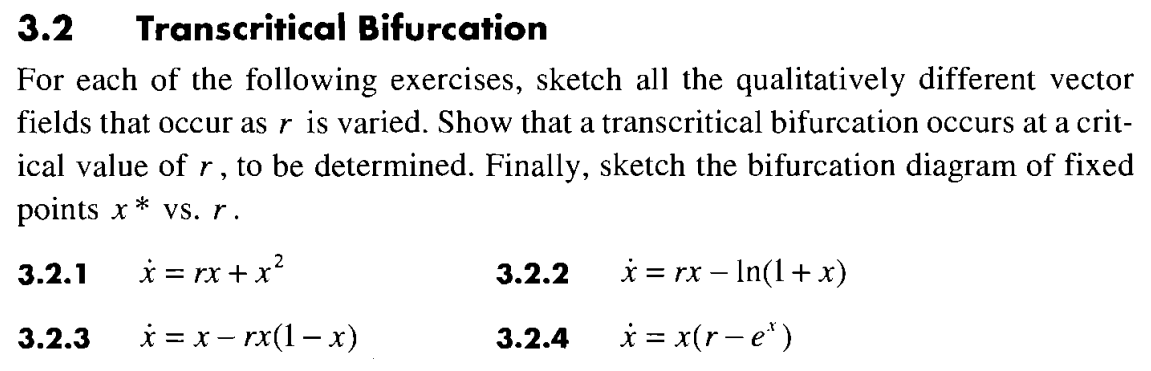

Para este tipo de bifurcación, se analiza el siguiente sistema:


$$\dot{x} =x\left(r-e^x \right)\ldotp$$


Donde $r$ es el parámetro de bifurcación

clc;clear;close all
disp("Ejercicio 3.2.4");
syms x r
Fsn = x*(r-exp(x))

% GRAFICA X*(x) con variantes de r:
r_desde=0; r_hasta=2; r_paso=1;
r_grafica=r_desde:r_paso:r_hasta; %Asigno valor.
x_desde=-2; x_hasta=2;
x_grafica=linspace(x_desde,x_hasta,100);
for i = 1:length(r_grafica)
    Fsn_grafica=real(subs(subs(Fsn,r,r_grafica(i)),x,x_grafica)); %sustituye r y x por valor numéricos.
    plot(x_grafica,Fsn_grafica); %Grafica Fsn con variantes de r.
    hold on;
end
ylim([-5 5])
grid on
title("X*(x)");
xlabel("x");
ylabel("X*");
% Crear leyenda para indicar valores de r
legendStrings = cellstr(num2str(r_grafica', 'r=%g'));
legend(legendStrings, 'Location', 'best');
hold off;

Para analizar este sistema, se encuentra los PE, linealizando alrededor de estos puntos y se analiza la estabilidad de cada uno.

xss_sn = simplify(solve(Fsn==0,x),"Steps",100) %resuelve eca, despeja X y simplifica hasta 100 pásos.

En este caso, para los tres PE se hace el siguiente análisis:

- Para $x_a =0$

Se tiene que el jacobiano $A=r-1$, para este caso $r<1$, con el fin de tener un valor estable para este polo, de lo contrario es inestable para $r>1$. 

- Para $x_b =\ln \left(r\right)$

Se tiene que el jacobiano $A=$$-r*\ln \left(r\right)$, se debe cumplir que $r>0\;$, para que los valores de $x_b$ sean reales. Además, si $r>1$ el polo es estable, de lo contrario es inestable para $r<1$.

Por ello en este caso 1 es el punto de bifurcación.

A = jacobian(Fsn,x); %Linealiza.

A_a = subs(A,x,xss_sn(1)) % Para el punto de equilibrio 1.
A_b = subs(A,x,xss_sn(2)) % Para el punto de equilibrio 2.

%Asigna valor para resolver para ese punto (mas factible) quiero resultado REAL:
r_asignado=1.5 %Asignamos valor para probar.
disp("Si el resultado del jacobiano da negativo, el polo es estable, 0 es medio estable: ")
reemplaza_r_asignado_A_a=subs(A_a,r,r_asignado)
reemplaza_r_asignado_A_b=subs(A_b,r,r_asignado)

En este caso, para los dos PE se hace el siguiente análisis:

El punto de bifurcación es r=1.

Con el  jacobiano $A$, en el punto simpre y cuando que el valor dentro de la raiz sea mayor a cero,  PE es estable.

xss_sn_num = double(subs(xss_sn,r,r_asignado))
disp("Los valores xss_sn_num es a donde tienden o se aleja en gráfica X vs t")

## Simulación de la Bifurcación Saddle - Node

Tsim = 60;              % Tiempo de simulación
Ts = 0.1;               % Periodo de muestreo
x0 = 0.1;                 % Condiciones iniciales Modificarse ++++++++++++++
disp("Condición inicial: "+ x0);
Ns = round(Tsim/Ts);    % Iteraciones
r_sim = linspace(r_desde,r_hasta,Ns); % Debe modificarse+++++++++++++++++++++++
t_sim = linspace(0,Ns*Ts,Ns);

% Solución ED
for i = 1:Ns
    % Simulación de la ED

    [t1,xd] = ode45(@(t,x) saddlenode_324(t,x,r_asignado), [0 Ts], x0); %REVISAR SI DEBE PONERSE R ASIGNADO +++++++++++++++++++
    x0 = xd(end,:)';

    % Análisis de Bifurcación

    fr(:,i) = double(subs(xss_sn,r,r_sim(i)));

    if imag(fr(:,i)) ~= 0
        fr(:,i) = NaN;      % Elimina los valores imaginarios cuando evalúa los posibles valores de r en los PE
    end
 
    % Guardar valores
    x_sim(i) = x0;
end

% Gráficas

figure("Name","Solución del sistema y diagrama de bifurcación")

%subplot(1,2,1)
plot(t_sim,x_sim,LineWidth=2)
xlabel("Tiempo [s]")
ylabel("Magnitud")
title("Solución x vs t")
grid on

%subplot(1,2,2)
plot(r_sim(r_sim < 1), real(fr(1, r_sim < 1)), 'LineWidth', 2, 'Color', 'r');
hold on
plot(r_sim(r_sim > 1), real(fr(2, r_sim > 1)), 'LineWidth', 2, 'Color', 'g');
plot(r_sim(r_sim > 1), real(fr(1, r_sim > 1)), 'LineWidth', 2, 'Color', 'r','LineStyle', '--');
plot(r_sim(r_sim < 1), real(fr(2, r_sim < 1)), 'LineWidth', 2, 'Color', 'g', 'LineStyle', '--');
grid on
title("Diagrama de bifurcación r vs x^*")
xlabel("r")
ylabel("x^*")
legend(["x_a" "x_b"])
hold off


Los valores que aparecen entre -2 y +2 no deben ser tenidos en cuenta, ya que estos valores cuentan con parte imaginaria y por ahora, eso no tiene sentido

#### Bifurcación Saddle - Node

function dxdt = saddlenode_324(t,x,r)
    dxdt = x*(r-exp(x));
end


# Punto 3.4.6  Pitchfork Bifurcation.

#### Se pide calcular valores de r en los que la bifurcación ocurre. Graficar diagrama de bifurcación de puntos X* vs r.

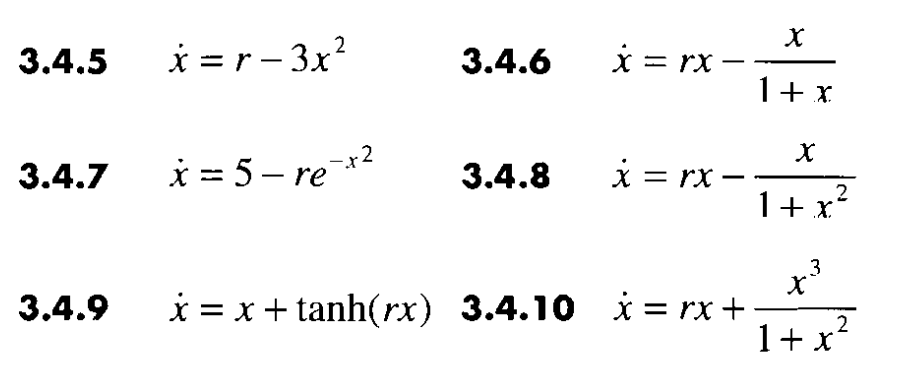

Para este tipo de bifurcación, se analiza el siguiente sistema:


$$\dot{x} =r*x-\frac{x}{\left(1+x\right)}\ldotp$$


Donde $r$ es el parámetro de bifurcación

clc;clear;close all
disp("Ejercicio 3.4.6");

Ejercicio 3.4.6


syms x r
Fsn = r*x-x/(1+x)

$$Fsn = r\,x-\frac{x}{x+1}$$

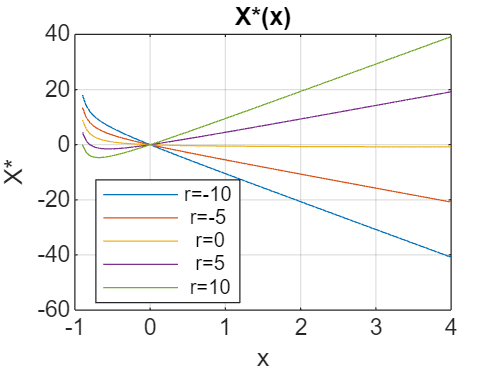


% GRAFICA X*(x) con variantes de r:
r_desde=-10; r_hasta=10; r_paso=5;
r_grafica=r_desde:r_paso:r_hasta; %Asigno valor.
x_desde=-0.9; x_hasta=4;
x_grafica=linspace(x_desde,x_hasta,100);
for i = 1:length(r_grafica)
    Fsn_grafica=real(subs(subs(Fsn,r,r_grafica(i)),x,x_grafica)); %sustituye r y x por valor numéricos.
    plot(x_grafica,Fsn_grafica); %Grafica Fsn con variantes de r.
    hold on;
end
%ylim([-15 15])
grid on
title("X*(x)");
xlabel("x");
ylabel("X*");
% Crear leyenda para indicar valores de r
legendStrings = cellstr(num2str(r_grafica', 'r=%g'));
legend(legendStrings, 'Location', 'best');
hold off;

Para analizar este sistema, se encuentra los PE, linealizando alrededor de estos puntos y se analiza la estabilidad de cada uno.

xss_sn = simplify(solve(Fsn==0,x),"Steps",100) %resuelve eca, despeja X y simplifica hasta 100 pásos.

$$xss\_sn = \left(\begin{array}{c} 0\\ \frac{1}{r}-1 \end{array}\right)$$

En este caso, tenemos 2 PE. Por lo que se linealiza en estos puntos

A = jacobian(Fsn,x) %Linealiza.

$$A = r+\frac{x}{{\left(x+1\right)}^{2}}-\frac{1}{x+1}$$

A_a = subs(A,x,xss_sn(1)) % Para el punto de equilibrio 1.

$$A\_a = r-1$$

A_b = subs(A,x,xss_sn(2)) % Para el punto de equilibrio 2.

$$A\_b = r^{2}\,\left(\frac{1}{r}-1\right)$$

r_asignado=0.5%Asignamos valor para probar.

r_asignado = 0.5000

disp("Si el resultado del jacobiano da negativo, el polo es estable, 0 es medio estable: ")

Si el resultado del jacobiano da negativo, el polo es estable, 0 es medio estable: 


reemplaza_r_asignado_A_a=subs(A_a,r,r_asignado)

$$reemplaza\_r\_asignado\_A\_a = -\frac{1}{2}$$

reemplaza_r_asignado_A_b=subs(A_b,r,r_asignado)

$$reemplaza\_r\_asignado\_A\_b = \frac{1}{4}$$

En este caso, para los tres PE se hace el siguiente análisis:

- Para $x_a =0$

Se tiene que el jacobiano $A=r-1$, para este caso $r<1$, con el fin de tener un valor **estable** para este polo, de lo contrario es inestable para $r>1$. 

- Para $x_b =\frac{1}{r}-1$

Se tiene que el jacobiano $A=$$r^2 *\left(\frac{1}{r}-1\right)$, se debe cumplir que $r\not= 0\;$ para que sea real. Además, si $r>1$ el polo es **estable**, de lo contrario es inestable para $r<1$.

xss_sn_num = double(subs(xss_sn,r,r_asignado))

xss_sn_num =      0
     1


disp("Los valores xss_sn_num es a donde tienden o se aleja en gráfica X vs t")

Los valores xss_sn_num es a donde tienden o se aleja en gráfica X vs t


## Simulación de la Bifurcación Saddle - Node

Tsim = 40;              % Tiempo de simulación
Ts = 0.1;               % Periodo de muestreo
x0 = -0.7;                 % Condiciones iniciales Modificarse ++++++++++++++
disp("Condición inicial: "+ x0);

Condición inicial: -0.7


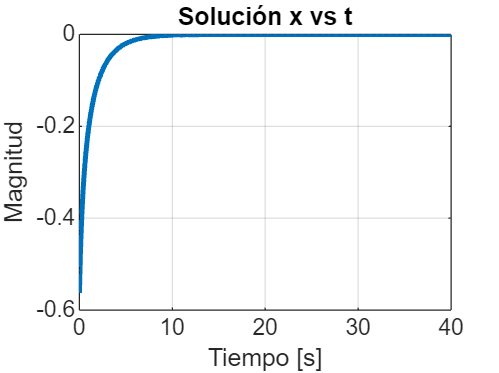

Ns = round(Tsim/Ts);    % Iteraciones
r_sim = linspace(r_desde,r_hasta,Ns); % Debe modificarse+++++++++++++++++++++++
t_sim = linspace(0,Ns*Ts,Ns);

% Solución ED
for i = 1:Ns
    % Simulación de la ED

    [t1,xd] = ode45(@(t,x) saddlenode_346(t,x,r_asignado), [0 Ts], x0); %REVISAR SI DEBE PONERSE R ASIGNADO +++++++++++++++++++
    x0 = xd(end,:)';

    % Análisis de Bifurcación

    fr(:,i) = double(subs(xss_sn,r,r_sim(i)));

    if imag(fr(:,i)) ~= 0
        fr(:,i) = NaN;      % Elimina los valores imaginarios cuando evalúa los posibles valores de r en los PE
    end
 
    % Guardar valores
    x_sim(i) = x0;
end

% Gráficas

figure("Name","Solución del sistema y diagrama de bifurcación")

%subplot(1,2,1)
plot(t_sim,x_sim,LineWidth=2)
xlabel("Tiempo [s]")
ylabel("Magnitud")
title("Solución x vs t")
grid on
hold off

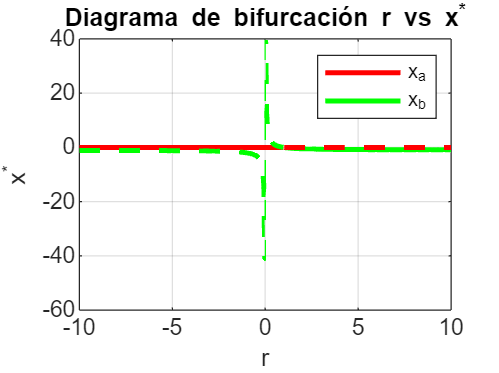


%----------
plot(r_sim(r_sim < 1), real(fr(1, r_sim < 1)), 'LineWidth', 2, 'Color', 'r');
hold on
plot(r_sim(r_sim > 1), real(fr(2, r_sim > 1)), 'LineWidth', 2, 'Color', 'g');
plot(r_sim(r_sim > 1), real(fr(1, r_sim > 1)), 'LineWidth', 2, 'Color', 'r', 'LineStyle', '--');
plot(r_sim(r_sim < 1 & r_sim ~= 0), real(fr(2,r_sim < 1 & r_sim ~= 0)), 'LineWidth', 2, 'Color', 'g', 'LineStyle', '--');
grid on
title("Diagrama de bifurcación r vs x^*")
xlabel("r")
ylabel("x^*")
legend(["x_a" "x_b"])
hold off

Los valores que aparecen entre -2 y +2 no deben ser tenidos en cuenta, ya que estos valores cuentan con parte imaginaria y por ahora, eso no tiene sentido

#### Bifurcación Saddle - Node

function dxdt = saddlenode_346(t,x,r)
    dxdt = r*x-x/(1+x);
end